**Modeling Frog Egg Growth Through 1D Piecewise Interpolation**

I applied 1D piecewise interpolation techniques to model the growth patterns of frog eggs. Interpolation is a valuable tool for estimating values between measured data points, especially in ecological studies where data collection can be sparse. By using different interpolation methods, such as linear, nearest, and spline, I analyzed how frog egg growth trends can be predicted with varying levels of accuracy and smoothness.

I began by defining data points representing frog egg growth measurements at specific times. These data points, simulated with random values, mimic observations collected over time.

Using the `interp1` function in MATLAB, I explored several interpolation techniques:

- **Linear Interpolation**: Estimates values between points by connecting them with straight lines.

- **Nearest, Next, and Previous Interpolation**: Piecewise constant methods that assume the interpolated value equals the nearest, next, or previous data point.

- **Shape-Preserving Cubic Interpolation (PCHIP)**: Ensures smooth transitions without overshooting.

- **Spline Interpolation**: Produces smooth curves ideal for capturing natural growth patterns.

I plotted the interpolated growth data for each method to observe how the predictions varied. Methods like linear and spline interpolation provided smoother transitions, making them suitable for modeling biological growth. Piecewise constant methods (nearest, next, and previous) were less smooth but computationally efficient.

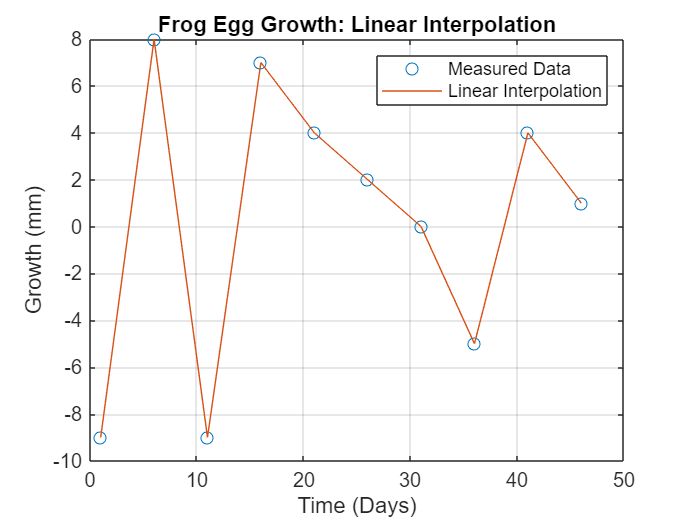

% Step 1: Define the frog egg growth data
x = 1:5:50; 
% I defined the time points (x) at which frog egg growth was measured, spaced at intervals of 5 units.

y = randi([-10, 10], 1, 10); 
% I generated random growth values (y) to simulate measurements of frog egg growth over time.

% Step 2: Define the points for interpolation
z = 0:0.25:50; 
% I created a finer set of time points (z) to estimate growth values between the original measurements.

% Step 3: Perform linear interpolation
z_y_linear = interp1(x, y, z, 'linear'); 
% I used linear interpolation to connect the original data points with straight lines, providing a simple and smooth approximation.

% Visualize linear interpolation
figure; 
plot(x, y, 'o', z, z_y_linear, '-'); 
% I plotted the original data points and the linearly interpolated values.
xlabel('Time (Days)'); 
ylabel('Growth (mm)'); 
title('Frog Egg Growth: Linear Interpolation'); 
legend('Measured Data', 'Linear Interpolation'); 
grid on;

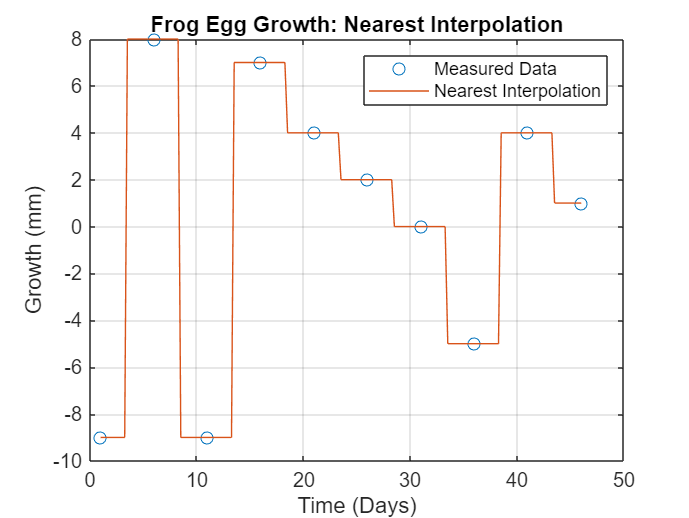


% Step 4: Perform nearest interpolation
z_y_nearest = interp1(x, y, z, 'nearest'); 
% I used nearest interpolation, where each interpolated value matches the nearest data point.

% Visualize nearest interpolation
figure; 
plot(x, y, 'o', z, z_y_nearest, '-'); 
xlabel('Time (Days)'); 
ylabel('Growth (mm)'); 
title('Frog Egg Growth: Nearest Interpolation'); 
legend('Measured Data', 'Nearest Interpolation'); 
grid on;

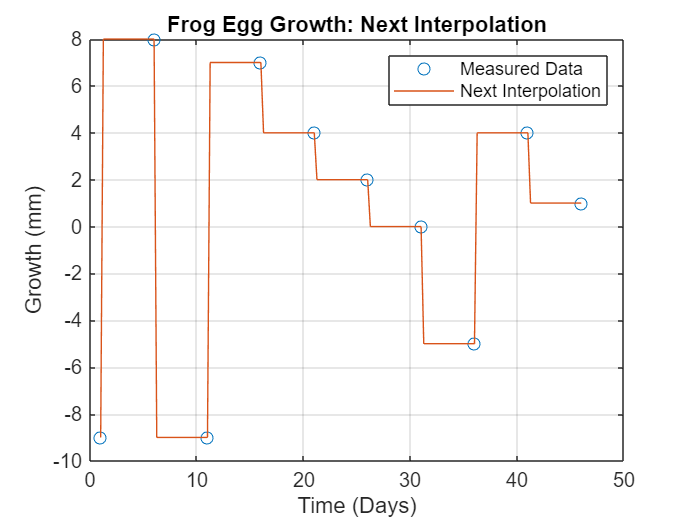


% Step 5: Perform next interpolation
z_y_next = interp1(x, y, z, 'next'); 
% I applied next interpolation, where each interpolated value matches the next data point.

% Visualize next interpolation
figure; 
plot(x, y, 'o', z, z_y_next, '-'); 
xlabel('Time (Days)'); 
ylabel('Growth (mm)'); 
title('Frog Egg Growth: Next Interpolation'); 
legend('Measured Data', 'Next Interpolation'); 
grid on;

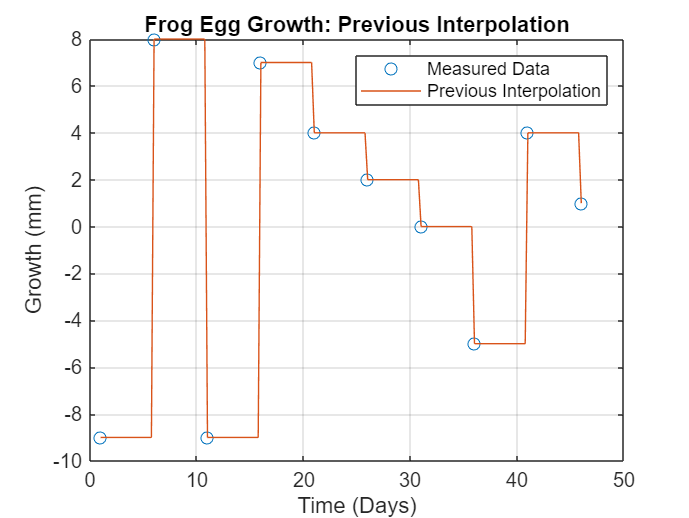


% Step 6: Perform previous interpolation
z_y_previous = interp1(x, y, z, 'previous'); 
% I applied previous interpolation, where each interpolated value matches the previous data point.

% Visualize previous interpolation
figure; 
plot(x, y, 'o', z, z_y_previous, '-'); 
xlabel('Time (Days)'); 
ylabel('Growth (mm)'); 
title('Frog Egg Growth: Previous Interpolation'); 
legend('Measured Data', 'Previous Interpolation'); 
grid on;

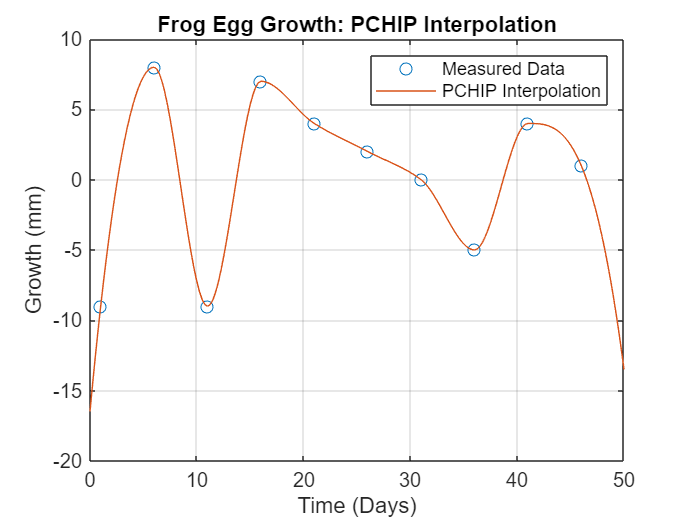


% Step 7: Perform PCHIP (shape-preserving) interpolation
z_y_pchip = interp1(x, y, z, 'pchip'); 
% I used PCHIP interpolation to create a smooth curve that preserves the shape of the data without overshooting.

% Visualize PCHIP interpolation
figure; 
plot(x, y, 'o', z, z_y_pchip, '-'); 
xlabel('Time (Days)'); 
ylabel('Growth (mm)'); 
title('Frog Egg Growth: PCHIP Interpolation'); 
legend('Measured Data', 'PCHIP Interpolation'); 
grid on;

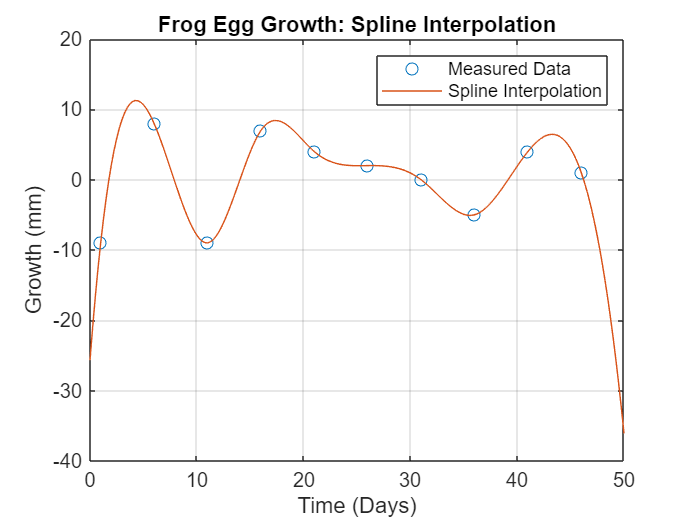


% Step 8: Perform spline interpolation
z_y_spline = interp1(x, y, z, 'spline'); 
% I applied spline interpolation for the smoothest and most natural transitions between data points.

% Visualize spline interpolation
figure; 
plot(x, y, 'o', z, z_y_spline, '-'); 
xlabel('Time (Days)'); 
ylabel('Growth (mm)'); 
title('Frog Egg Growth: Spline Interpolation'); 
legend('Measured Data', 'Spline Interpolation'); 
grid on;